# SISO

% load("results\shin_siso.mat");
% 常用参数
legend_name = {'true', 'd-ISIM (full)', 'd-ISIM (reduce)', 'IV4', 'SIM (time)', 'SIM (freq)'};
font_size = 10; line_width = 1.5;

scatter

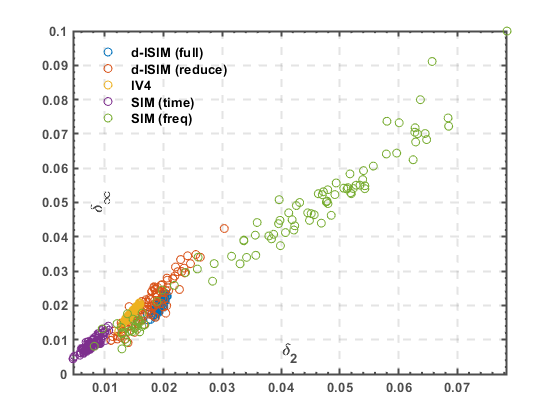

fig = figure; ax = axes(fig);
scatter(ax, analy_h2.', analy_hinf.');
plotLegend(legend_name(2:end), font_size, line_width, 'northwest');
betterFig(fig, font_size, line_width);
% 坐标轴
Xlm = xlim; Ylm = ylim;  % get x, y axis limits, so can position relative instead of absolute
xlabel(ax, '\delta_2', Position=[mean(Xlm) 0.10*diff(Ylm)], FontSize=font_size+2, FontWeight='bold', FontName='Arial');
ylabel(ax, '\delta_\infty', Position=[0.15*diff(Xlm) mean(Ylm)], FontSize=font_size+2, FontWeight='bold', FontName='Arial');
exportgraphics(fig, 'results\siso_scatter.eps')

响应图

函数

function betterFig(fig, font_size, line_width)
    % 寻找axes
    child_axes = findobj(fig.Children, 'type', 'Axes');
    for iter_axes = 1:length(child_axes)
        % 优化格式
        plotAux(child_axes(iter_axes), font_size, line_width);
        % 寻找line
        child_line = findobj(child_axes(iter_axes), 'type', 'Line');
        for iter_line = 1:length(child_line)
            plotAux(child_line(iter_line), font_size, line_width);
        end
    end
end